# Week 2: Ridgid Motion and Denso Analysis

Demargio Glanville, WPI Graduate Student, ddglanville@WPI.edu

## Introduction

The goal of this assignment was to use our accumulated knowledge to discuss and analyze an industrial "Pick and Place" Robot. Before beginning the discussion, a bit of background knowledge was applied to problems 2-13 and 2-37 of the 2nd edition "Robot Modeling and Control" textbook by Mark W Spong, Seth Hutchinson, and M.Vidyasagar.

The first problem, 2-13, asked use to create a matrix product which would result in the appropriate rotation matrix. Understanding how to use the current versus world frame equations was essential. 

This knowledge served as the basis for the next problem, 2-37. This problem asked for three homogeneous matrices  give a figure as reference. Then it asked us to demonstrate that the product of two of the matrices  equaled the third.

After practicing the knowledge, it was applied to a discussion of a Denso Robot. First breaking the robot in to a set of satisfactory frames and then demonstrating the homogeneous transformations from Base to Manipulator. Finally a motion analysis was done.

Overall, the robot is very effective for task which do not need a high volume workspace. Even more so, the robot does extremely well in an environment  where more motion is required in the plane perpendicular to its manipulator. 

## Materials and Methods

### Nomenclature:

- $S_{\theta ,\phi }$         Sine with relation to $\theta$ or $\phi$

- $C_{\theta ,\phi }$        Cosine with relation to $\theta$ or $\phi$

- $R_j^i$           Rotational Matrix in frame $j$ in the coordinate system of $i$

- $R_{i,j}$          Basic Rotation Matrix about $i$ axis and by$j$ radians

- $H_j^i$          Homogeneous Matrix in frame $j$ in the coordinate system of $i$

- $O$            Coordinate Frame

- $d$             Displacement vector

- $\theta ,\phi ,\varphi ,\alpha$ Angle in radians

clear % Removing previously existing variables.

syms alpha theta psi phi

### Process:

####     2-13

Problem 2-13 gave a sequence of rotational transformations and asked for an equation which would result in an equivalent rotational matrix. The sequence was as follows:

Rotate about $\phi$about the world x-axis.

Rotate about $\theta$about the world z-axis.

Rotate about $\varphi$about the current x-axis.

Rotate about $\alpha$about the world z-axis.

From each line, two significant pieces of information were gathered, the reference frame and the axis of rotation. The frame of reference was either world frame or current frame. World frame refers to a fixed coordinate in the environment. It can be the base of the robot or the center of a work space. Current frame is literal, it refers to the most recent frame in use. Unlike the world frame, current frame will change as we transform the frame. It was important to know the differences between the frames because, each as an associated equation in regards to rotations. 

         $R_2^0 =R_1^0 R_2^1$                                                                                                                                                                    (**Equation 2.17**)

         $R_2^0 =RR_1^0$                                                                                                                                                                    (**Equation 2.23**)

The first equation, 2.17 is the equation for rotations in respect to the current frame. The equation after, 2.23, is the equation for rotations in respect to a fixed frame, or world frame. It was important to note the difference between the two. 2.17 multiplies the rotation, post reference. In contrast, 2.23 does pre-multiplication. The two are opposites but, it was critical not to confuse them.

In addition to the rotation equations, it was essential to know the basic rotation matrices. There is an equation associated with each axis.

 $R_{z,\theta } =\left\lbrack \begin{array}{ccc}
C_{\theta }  & {-S}_{\theta }  & 0\\
S_{\theta }  & C_{\theta }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                                                                    (**Equation 2.3**)

$R_{x,\theta } =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & C_{\theta }  & {-S}_{\theta } \\
0 & S_{\theta }  & C_{\theta } 
\end{array}\right\rbrack$                                                                                                                                                                    (**Equation 2.7**)

$R_{y,\theta } =\left\lbrack \begin{array}{ccc}
C_{\theta }  & 0 & S_{\theta } \\
0 & 1 & 0\\
{-S}_{\theta }  & 0 & C_{\theta } 
\end{array}\right\rbrack$                                                                                                                                                                    (**Equation 2.8**)

The equations made is simple to rotate frames to match another thus making it easier to project motions onto other frames. 

With the equations and concepts covered, the problem was straightforward. The first rotation was in the world frame about the x-axis. The second rotation was also in the world frame but about the z-axis. They could be represented as the following equation.

$R=R_2^0 R_1^0$                                                                                                                                                                                (**Equation 1**)

The world frame was used in this case thus, the second matrix, $R_2^0$ was pre-multiplied. The third equation called for a rotation about the x-axis in the current frame, thus the matrix was post-multiplied, as shown below.

$R=\left(R_2^0 R_1^0 \right)R_3^2$                                                                                                                                                                                (**Equation 2**)

 The fourth rotation was about the z-axis in the world frame. It was pre-multiplied resulting in the final equation.

$R=R_4^0 \left(\left(R_2^0 R_1^0 \right)R_3^2 \right)$                                                                                                                                                                                (**Equation 3**)

Then, using the Basic rotation matrices, Equation three was changed to matrix form below which could then be solved for the final rotation matrix.

$R=\left\lbrack \begin{array}{ccc}
C_{\alpha }  & {-S}_{\alpha }  & 0\\
S_{\alpha }  & C_{\alpha }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \bullet \left(\left(\left\lbrack \begin{array}{ccc}
C_{\theta }  & {-S}_{\theta }  & 0\\
S_{\theta }  & C_{\theta }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \bullet \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & C_{\phi }  & {-S}_{\phi } \\
0 & S_{\phi }  & C_{\phi } 
\end{array}\right\rbrack \right)\bullet \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & C_{\varphi }  & {-S}_{\varphi } \\
0 & S_{\varphi }  & C_{\varphi } 
\end{array}\right\rbrack \right)$                                                                                                                                                                               (**Equation 4)**

####     2-37

Problem 2-37 asked for three homogeneous transformations given the diagram below.

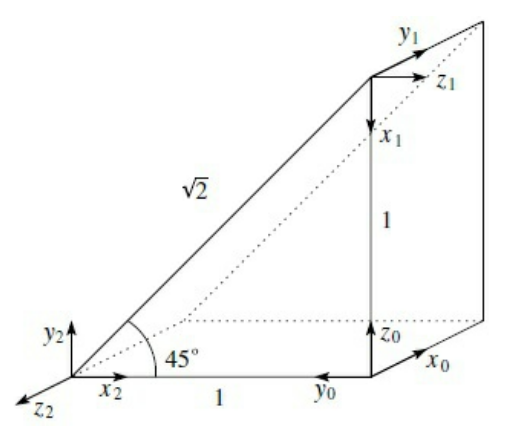

**(Figure 2.13)**

With figure 2.13, the homogeneous transformations,$H_1^0$,$H_2^0$, and $H_2^1$. A homogeneous transformation is a rigid motion, rotation then translation. The relation can be seen below.

$H=\left\lbrack \begin{array}{cc}
R & d\\
0 & 1
\end{array}\right\rbrack$                                                                                                                                             (**Equation 2.67)**

In equation  2.67, $R$ represents the rotational matrix (3x3 matrix) and $d$ is the displacement vector (3x1 matrix). In its expanded form, equation 2.67 would actually be a 4x4 matrix, which will be demonstrated further down.

When solving for the homogeneous transformations, the rotational matrix was defined. To define the rotational matrix, the coordinate system must be rotated to match the frame. In the case of $H_1^0$, the $O_0$ frame was rotated about the z-axis $\theta \;$then rotated about the y-axis $\phi$. By multiplying the related Basic Rotation Matrices, $Z\bullet Y$, the equation below is produced.

$R_1^0 =\left\lbrack \begin{array}{ccc}
C_{\theta }  & {-S}_{\theta }  & 0\\
S_{\theta }  & C_{\theta }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \bullet \left\lbrack \begin{array}{ccc}
C_{\phi }  & 0 & S_{\phi } \\
0 & 1 & 0\\
{-S}_{\phi }  & 0 & C_{\phi } 
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{ccc}
C_{\theta } C_{\phi }  & {-S}_{\theta }  & C_{\theta } S_{\phi } \\
S_{\theta } C_{\phi }  & C_{\theta }  & S_{\theta } S_{\phi } \\
{-S}_{\phi }  & 0 & C_{\phi } 
\end{array}\right\rbrack =R_1^0$                                                                                                                                             (**Equation 5)**

With the Rotation matrix defined, the displacement vector was next. The displacement vector holds the distance on each axis from the coordinate system to the frame. in the case of $H_1^0$, $O_0$ is 1 unit from $O_1$ in the direction of the z-axis. With this the Displacement vector for $H_1^0$ was found to be the matrix below.

$d_1^0 =\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$                                                                                                                                             (**Equation 6)**

With everything defined, they were used in equation 2.67 to produce the solution to $H_1^0$.

$H_1^0 =\left\lbrack \begin{array}{cccc}
C_{\theta } C_{\phi }  & {-S}_{\theta }  & C_{\theta } S_{\phi }  & 0\\
S_{\theta } C_{\phi }  & C_{\theta }  & S_{\theta } S_{\phi }  & 0\\
{-S}_{\phi }  & 0 & C_{\phi }  & 1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                      (**Equation 7)**

The same process was repeated to solve for $H_2^0$. The frame $O_0$ was first rotated about the z-axis $-\theta$ and then rotated about the x-axis $\phi$. With the basic rotation matricies the resulting rotation matrix is a follows.

$R_2^0 =\left\lbrack \begin{array}{ccc}
C_{\theta }  & {-S}_{\theta }  & 0\\
S_{\theta }  & C_{\theta }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \bullet \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & C_{\phi }  & {-S}_{\phi } \\
0 & S_{\phi }  & C_{\phi } 
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{ccc}
C_{\theta }  & {-S}_{\theta } C_{\phi }  & S_{\theta } S_{\phi } \\
S_{\theta }  & C_{\theta } C_{\phi }  & C_{\theta } S_{\phi } \\
0 & {-S}_{\phi }  & C_{\phi } 
\end{array}\right\rbrack =R_2^0$                                                                                                                                             (**Equation 8)**

Here, $O_0$ and $O_2
$ were displaced by one unit in the y direction thus, the displacement vector is as follows:

$d_2^0 =\left\lbrack \begin{array}{c}
0\\
1\\
0
\end{array}\right\rbrack$                                                                                                                                             (**Equation 9)**

Then the two were combined in equation 2.67.

$H_2^0 =\left\lbrack \begin{array}{cccc}
C_{\theta }  & {-S}_{\theta } C_{\phi }  & S_{\theta } S_{\phi }  & 0\\
S_{\theta }  & C_{\theta } C_{\phi }  & C_{\theta } S_{\phi }  & 1\\
0 & S_{\phi }  & C_{\phi }  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                   (**Equation 10)**

The the homogeneous transformation was found for $H_2^1$. Beginning with the Rotation matrix, $O_0
$ was rotated $\theta$ about the z-axis and the rotated $-\phi \;$about the y-axis.

$R_2^1 =\left\lbrack \begin{array}{ccc}
C_{\theta }  & {-S}_{\theta }  & 0\\
S_{\theta }  & C_{\theta }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \bullet \left\lbrack \begin{array}{ccc}
C_{\phi }  & 0 & S_{\phi } \\
0 & 1 & 0\\
{-S}_{\phi }  & 0 & C_{\phi } 
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{ccc}
{C_{\theta } C}_{\phi }  & -S_{\theta }  & {C_{\theta } S}_{\phi } \\
S_{\theta } C_{\phi }  & C_{\theta }  & {-S}_{\theta } \\
-S_{\phi }  & 0 & C_{\phi } 
\end{array}\right\rbrack =R_2^1$                                                                                                                                             (**Equation 11)**

The displacement vector was more complex for $H_2^1$ since there is displacement in both the X and Z directions. Although it was more complex, it was not any more difficult than the previous vectors, as seen in Equation 12.

$d_2^1 =\left\lbrack \begin{array}{c}
1\\
0\\
-1
\end{array}\right\rbrack$                                                                                                                                             (**Equation 12)**

Then the components were once again assembled using Equation 2.67.

$H_2^1 =\left\lbrack \begin{array}{cccc}
{C_{\theta } C}_{\phi }  & -S_{\theta }  & {C_{\theta } S}_{\phi }  & 1\\
S_{\theta } C_{\phi }  & C_{\theta }  & {-S}_{\theta }  & 0\\
-S_{\phi }  & 0 & C_{\phi }  & -1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                  (**Equation 13)**

Once all of the homogeneous transformations had been solved for, the second part of the problem was addressed. The problem also asked to prove $H_2^0 =H_1^0 \;H_2^1$. Using the previously solved for matrices in the proof equation made the process simple.

$H_2^0 =H_1^0 \;H_2^1 \Rightarrow \left\lbrack \begin{array}{cccc}
C_{\theta }  & {-S}_{\theta } C_{\phi }  & S_{\theta } S_{\phi }  & 0\\
S_{\theta }  & C_{\theta } C_{\phi }  & C_{\theta } S_{\phi }  & 1\\
0 & S_{\phi }  & C_{\phi }  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
C_{\theta } C_{\phi }  & {-S}_{\theta }  & C_{\theta } S_{\phi }  & 0\\
S_{\theta } C_{\phi }  & C_{\theta }  & S_{\theta } S_{\phi }  & 0\\
{-S}_{\phi }  & 0 & C_{\phi }  & 1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \bullet \left\lbrack \begin{array}{cccc}
{C_{\theta } C}_{\phi }  & -S_{\theta }  & {C_{\theta } S}_{\phi }  & 1\\
S_{\theta } C_{\phi }  & C_{\theta }  & {-S}_{\theta }  & 0\\
-S_{\phi }  & 0 & C_{\phi }  & -1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                      (**Equation 14)**

####     Denso Discussion

The Denso Robot was a RRP SCARA, also known as "Pick and Place". From pictures on the website and the catalog, a figure representing the robot was made.

 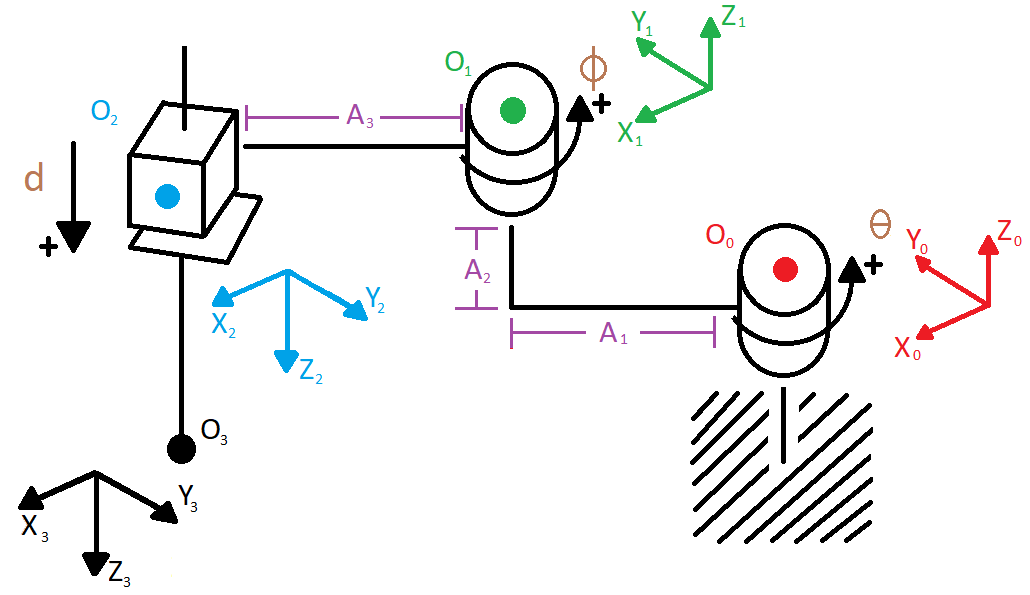

**(Figure 1)**

As seen in the figure above, Joint $O_0$ is a rotational joint about the Z-axis. Its frame is represented in red. Joint $O_1$ is also a rotational joint about the Z- axis thus it looks very similar to $O_0$.The frame for $O_1$is represented in green. $O_1$ is offset from $O_0$ by links $A_1$ and $A_2$. In reality, $A_1$ and $A_2$ are actually one link however, $O_1$ is offset from $O_0$ in two directions thus, the link was separated into its parts for clarity. $O_2$ is a prismatic joint only moving in the Z-axis. The frame for $O_2$ is blue. Connecting $O_2$ to $O_1$  is link $A_3$.

Using the diagram a homogeneous transformation from $O_0$ to $O_2$, $H_2^0$, was created. From the diagram, it was clear $H_2^0 =H_1^0 \;H_2^1$. With this, $H_1^0$ was the first to be solved for. First the rotational matrix was found. Since the frames had the same orientation, there was no need for a rotational transformation. However, there was a need to account for the possible joint rotation,$\;\theta$, about the Z-axis.

$R_1^0 =\left\lbrack \begin{array}{ccc}
C_{\theta }  & {-S}_{\theta }  & 0\\
S_{\theta }  & C_{\theta }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                                                                    (**Equation 15**)

Then the displacement vector was solved. According to Figure 1, $A_1$ lies perfectly between the x and y axis and has has both x and y components while $A_2$ has only z components. Thus the displacement vector was as follows:

$d_1^0 =\left\lbrack \begin{array}{c}
A_1 \sin \left(\frac{\pi }{4}\right)\\
A_1 \cos \left(\frac{\pi }{4}\right)\\
A_2 
\end{array}\right\rbrack$                                                                                                                                       (**Equation 16)**

After, the two are used in the general homogeneous transformation equation.

$H_1^0 =\left\lbrack \begin{array}{cccc}
C_{\theta }  & {-S}_{\theta }  & 0 & A_1 \sin \left(\frac{\pi }{4}\right)\\
S_{\theta }  & C_{\theta }  & 0 & A_1 \cos \left(\frac{\pi }{4}\right)\\
0 & 0 & 1 & A_2 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                (**Equation 17)**

When solving for the rotational matrix of $H_2^1$, it was seen frame $O_2$ is frame $O_1$ but, rotated by $\varphi \;$about the x axis. There is also a need to account for the rotation in the joint of $O_1$ around the z axis.

$R_2^1 =\left\lbrack \begin{array}{ccc}
C_{\phi }  & {-S}_{\phi }  & 0\\
S_{\phi }  & C_{\phi }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \bullet \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & C_{\varphi }  & {-S}_{\varphi } \\
0 & S_{\varphi }  & C_{\varphi } 
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{ccc}
C_{\phi }  & {-S}_{\phi } C_{\varphi }  & S_{\phi } S_{\varphi } \\
S_{\phi }  & C_{\phi } C_{\varphi }  & -C_{\phi } S_{\varphi } \\
0 & S_{\varphi }  & C_{\varphi } 
\end{array}\right\rbrack$                                                                                                                                                                    (**Equation 18**)

As seen in Figure 1, similar to link $A_1$, $A_3$ lies perfectly between the x and y axis and has x and y components thus, the displacement vector is as follows:

 $d_2^1 =\left\lbrack \begin{array}{c}
A_3 \sin \left(\frac{\pi }{4}\right)\\
A_3 \cos \left(\frac{\pi }{4}\right)\\
0
\end{array}\right\rbrack$                                                                                                                                      (**Equation 19)**

The two were then used in equation 2.67.

$H_2^1 =\left\lbrack \begin{array}{cccc}
C_{\phi }  & {-S}_{\phi } C_{\varphi }  & S_{\phi } S_{\varphi }  & A_3 \sin \left(\frac{\pi }{4}\right)\\
S_{\phi }  & C_{\phi } C_{\varphi }  & -C_{\phi } S_{\varphi }  & A_3 \cos \left(\frac{\pi }{4}\right)\\
0 & S_{\varphi }  & C_{\varphi }  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                   (**Equation 20)**

Finally the homogeneous transformations were combined to form one matrix. $H_2^0 =H_1^0 \;H_2^1$

$H_2^0 =\left\lbrack \begin{array}{cccc}
C_{\theta }  & {-S}_{\theta }  & 0 & A_1 \sin \left(\frac{\pi }{4}\right)\\
S_{\theta }  & C_{\theta }  & 0 & A_1 \cos \left(\frac{\pi }{4}\right)\\
0 & 0 & 1 & A_2 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \bullet \left\lbrack \begin{array}{cccc}
C_{\phi }  & {-S}_{\phi } C_{\varphi }  & S_{\phi } S_{\varphi }  & A_3 \sin \left(\frac{\pi }{4}\right)\\
S_{\phi }  & C_{\phi } C_{\varphi }  & -C_{\phi } S_{\varphi }  & A_3 \cos \left(\frac{\pi }{4}\right)\\
0 & S_{\varphi }  & C_{\varphi }  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                   (**Equation 21)**

The prompt asked for the transformation at the tip of the manipulator, $H_3^0$. Thus one more transformation was needed where $H_3^0 =H_2^0 \;H_3^2 \;$. $O_3$, the tip of the manipulator, has the same frame orientation as the previous joint, $O_2$. It also does not have any associated rotation thus, the only factor is the displacement. Given there is not any rotation in $H_3^2$, $R_3^2$ will be represented as the matrix equivalent of 1, an Identity Matrix. 

$R_3^2 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                                                                    (**Equation 22**)

The displacement vector only has one element in the Z direction, the prismatic motion of joint $O_2$, denoted by $d$.

$d_3^2 =\left\lbrack \begin{array}{c}
0\\
0\\
d
\end{array}\right\rbrack$                                                                                                                                       (**Equation 23)**

With rotation and displacement, the Homogeneous transformation, $H_3^2$, resulted in the following.

$H_3^2 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                   (**Equation 24)**

Finally, solving for $H_3^0 =H_2^0 \;H_3^2 \;\Rightarrow H_3^0 =H_1^0 \;H_2^1 H_3^2$,

$H_3^0 =\left\lbrack \begin{array}{cccc}
C_{\theta }  & {-S}_{\theta }  & 0 & A_1 \sin \left(\frac{\pi }{4}\right)\\
S_{\theta }  & C_{\theta }  & 0 & A_1 \cos \left(\frac{\pi }{4}\right)\\
0 & 0 & 1 & A_2 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \bullet \left\lbrack \begin{array}{cccc}
C_{\phi }  & {-S}_{\phi } C_{\varphi }  & S_{\phi } S_{\varphi }  & A_3 \sin \left(\frac{\pi }{4}\right)\\
S_{\phi }  & C_{\phi } C_{\varphi }  & -C_{\phi } S_{\varphi }  & A_3 \cos \left(\frac{\pi }{4}\right)\\
0 & S_{\varphi }  & C_{\varphi }  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \bullet \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                   (**Equation 25)**

## Results

####     2-13

Using the derived equations and matrices, a code which could derive the matrix product with random values was created as a function.

The Function, MatrixProduct, produced a matrix using Equation 3, which was previously derived as the product matrix. The inputs into Equation 3 were Basic rotation matrices depending on the axis of rotation. The input angles for each of the matrices were randomly generated ranging from 0 to $2\pi$.



MatrixProduct(alpha,theta,phi,psi) % Solves for the product matirx

$$R\_5 = \left(\begin{array}{ccc} \cos\left(\alpha +\theta \right) & -\cos\left(\varphi +\psi \right)\,\sin\left(\alpha +\theta \right) & \sin\left(\alpha +\theta \right)\,\sin\left(\varphi +\psi \right)\\ \sin\left(\alpha +\theta \right) & \cos\left(\alpha +\theta \right)\,\cos\left(\varphi +\psi \right) & -\cos\left(\alpha +\theta \right)\,\sin\left(\varphi +\psi \right)\\ 0 & \sin\left(\varphi +\psi \right) & \cos\left(\varphi +\psi \right) \end{array}\right)$$

$$ans = \left(\begin{array}{ccc} 0.93336881664696169647044143857784 & -0.14894366329193922671159100445948 & -0.32655541225989165310394923835702\\ 0.35891872633097648970235127308115 & 0.38732827393816249283986508089583 & 0.84920795809803462095288750788313\\ 0 & -0.90983107958195252873423441997147 & 0.41497880262338560086732286436018 \end{array}\right)$$

####     2-37

Using figure 2.13, Homogeneous transformations were found for $H_2^0 ,\;H_1^{0,} \;{\;H}_2^1$. Using the rotation angles used to create the rotation matrices were simplified to the following forms where H1 is the transformation of frame one in system 0, H2 is the transformation of frame 2 in system 1, and H3 is the transformation of frame 2 in system 0.

theta_1 = -pi/2; % Theta for H1 in respect to the 0 system
theta_2 = pi/2; % Theta for H2 in respect to the 1 system
theta_3 = -pi/2; % Theta for H2 in respect to the 0 system

phi_1 = pi/2; % Phi for H1 in respect to the 0 system
phi_2 = -pi/2; % Phi for H2 in respect to the 1 system
phi_3 = pi/2; % Phi for H2 in respect to the 0 system

H_1 = [cos(sym(theta_1))*cos(sym(phi_1)) -sin(sym(theta_1)) cos(sym(theta_1))*sin(sym(phi_1)) 0;
       sin(sym(theta_1))*cos(sym(phi_1)) cos(sym(theta_1)) sin(sym(theta_1))*sin(sym(phi_1)) 0;
       -sin(sym(phi_1)) 0 cos(sym(phi_1)) 1;
       0 0 0 1] % 

$$H\_1 = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & -1 & 0\\ -1 & 0 & 0 & 1\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_2 = [cos(sym(theta_2))*cos(sym(phi_2)) -sin(sym(theta_2)) cos(sym(theta_2))*sin(sym(phi_2)) 1;
       sin(sym(theta_2))*cos(sym(phi_2)) cos(sym(theta_2)) -sin(sym(theta_2)) 0;
       -sin(sym(phi_2)) 0 cos(sym(phi_2)) -1;
       0 0 0 1]

$$H\_2 = \left(\begin{array}{cccc} 0 & -1 & 0 & 1\\ 0 & 0 & -1 & 0\\ 1 & 0 & 0 & -1\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_3 = [cos(sym(phi_3)) -sin(sym(theta_3))*cos(sym(phi_3)) sin(sym(theta_3))*sin(sym(phi_3)) 0;
       sin(sym(theta_3)) cos(sym(theta_3))*cos(sym(phi_3)) cos(sym(theta_3))*sin(sym(phi_3)) 1;
       0 sin(sym(phi_3)) cos(sym(phi_3)) 0;
       0 0 0 1]

$$H\_3 = \left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ -1 & 0 & 0 & 1\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Using the simplified matrices, $H_2^0 =H_1^0 \;H_2^1$ was then proven.

H_3 == H_1*H_2

$$ans = \left(\begin{array}{cccc} 0=0 & 0=0 & -1=-1 & 0=0\\ -1=-1 & 0=0 & 0=0 & 1=1\\ 0=0 & 1=1 & 0=0 & 0=0\\ 0=0 & 0=0 & 0=0 & 1=1 \end{array}\right)$$

####     Denso Analysis

Using Equation 25 and constants defined by the dimensions of the robot, we can create a simplified Homogeneous Transformation matrix to represent the motion of the robot. The Dimensions of the robot are as follows: $A_1$ = 205 mm, $A_2 \approx$115 mm (actual dimension not displayed), and $A_3 =$ 275 mm. Using these dimensions, the matrix can be simplified. For this Analysis, the arm will start at the 0 position relative to its coordinates rather than $\frac{\pi }{4}$.

%phi = 0;
%theta = 0;
psi = sym(-pi);

A_1 = sym(205);
A_2 = sym(115);
A_3 = sym(275);

syms d; %theta phi;

R1 = [cos(sym(theta)) -sin(sym(theta)) 0 A_1*sin(sym(0));
      sin(sym(theta)) cos(sym(theta)) 0 A_1*cos(sym(0));
      0 0 1 A_2;
      0 0 0 1];
R2 = [cos(sym(phi)) -sin(sym(phi))*cos(sym(psi)) sin(sym(phi))*sin(sym(psi)) A_3*sin(sym(0));
      sin(sym(phi)) cos(sym(phi))*cos(sym(psi)) -cos(sym(phi))*sin(sym(psi)) A_3*cos(sym(0));
      0 sin(sym(psi)) cos(sym(psi)) 0;
      0 0 0 1];
D = [1 0 0 0;
     0 1 0 0;
     0 0 1 sym(d);
     0 0 0 1];

H = simplify((R1*R2)*D)

$$H = \left(\begin{array}{cccc} \cos\left(\varphi +\theta \right) & \sin\left(\varphi +\theta \right) & 0 & -275\,\sin\left(\theta \right)\\ \sin\left(\varphi +\theta \right) & -\cos\left(\varphi +\theta \right) & 0 & 275\,\cos\left(\theta \right)+205\\ 0 & 0 & -1 & 115-d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Using this matrix, a graph was made demonstrating the motion of the tip as $\theta$ moved from 0 to $\pi$ over 1 degree increments, $\phi$ move from 0 to $\frac{\pi }{2}$ over .5 degree increments, and d ranging from 0 to 100 mm over 100/180 mm increments.

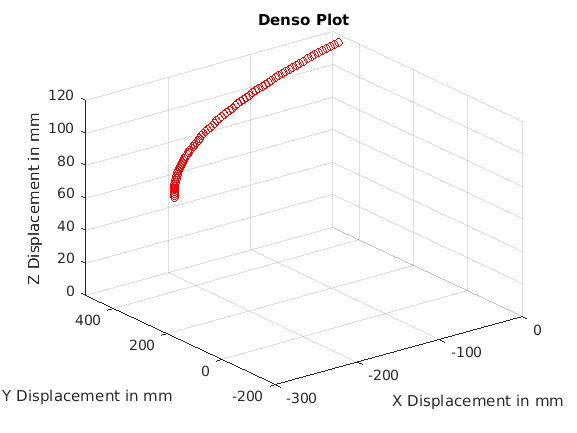

p = SolveH(H);

DensoPlot(p)

As expected, the motion of both rotational joint plus a motion in the Z-axis from the prismatic created a helix shaped plot.

##  Discussion

The results were as expected. Both problems 2-13 and 2-37 were good practice to learn what was needed to complete a motion analysis. I did most of the work on a piece of paper to make sure I understood what I was doing before I attempted to apply it in MatLab. Doing the problems by hand was time consuming and it led to an transcription error when I had to move my work to MatLab but, it did help. 

I did get stuck twice. Once on the second question because I used the wrong basic rotation vector but, wrote the correct configuration. The second time was while I was thinking of a way to plot the motion in question 3. I had to create two functions, one to use the symbolic homogeneous matrix and return a matrix of values, and another to plot the matrix. It required disassembling the matrix which was not ideal. I'm sure there was another way to plot the matrix in its entirety. I would have liked to add a silhouette or line to represent the arm as the function was being plotted. 

I do have an animation I made in SolidWorks but, it's revolving in the wrong direction.

 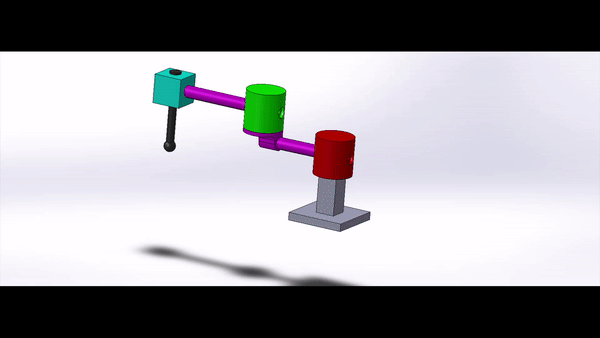

Overall, the most of the challenges faced was in presentation. Breaking down each problem into steps can be difficult as you must choose what can be omitted or assumed. How much detail is needed to properly explain a step? This is where most of my time was spent but, it was necessary.

## Reference

Denso Corperation. (2017). *DENSO Robotics Catalog*. DCatalog. https://html5.dcatalog.com/?docid=72c75621-8544-41b4-9afa-a7f60153efbd&page=32

Spong, M. W., Hutchinson, S., & Vidyasagar, M. (2020). *Robot Modeling and Control* (2nd ed.). Wiley.

### Functions

function MatrixProduct(alpha,theta,phi,psi)


    R_1 = [1 0 0; 
           0 cos(phi) -sin(phi);
           0 sin(phi) cos(phi)]; % Rotation matrix 1 in coordinate system 0 (Basic Rotation Matrix X)
    R_2 = [cos(theta) -sin(theta) 0; 
           sin(theta) cos(theta) 0;
           0 0 1]; % Rotation matrix 2 in coordinate system 0 (Basic Rotation Matrix Z)
    R_3 = [1 0 0; 
           0 cos(psi) -sin(psi);
           0 sin(psi) cos(psi)]; % Rotation matrix 3 in coordinate system 2 (Basic Rotation Matrix X)
    R_4 = [cos(alpha) -sin(alpha) 0; 
           sin(alpha) cos(alpha) 0;
           0 0 1]; % Rotation matrix 4 in coordinate system 0 (Basic Rotation Matrix Z)

    R_5 = simplify((R_4)*((R_2*R_1)*R_3)) % Equation 3
    
    alpha = double(rand*2*pi); % Random number from 0 to 2pi
    theta = double(rand*2*pi); % Random number from 0 to 2pi
    phi = double(rand*2*pi); % Random number from 0 to 2pi
    psi = double(rand*2*pi); % Random number from 0 to 2pi
    
    r_6 = zeros(3,3);
    
    subs(R_5);
    
    for i = 1:height(R_5)
        for j = 1:width(R_5)
            r_6(i,j) = subs(R_5(i,j));
        end
    end
    
    vpa(r_6)
    
end

function p = SolveH(H)
    t = [0:deg2rad(1):pi];
    ph = [0:deg2rad(.5):pi/2];
    di = [0:100/180:100];
    
    n = numel(di);
    p = zeros(n,3);
    
    for i = 1:n
        
        theta = t(1,i);
        phi = ph(1,i);
        d = di(1,i);
        
        f = subs(H);
        
        p(1,i) = f(1,4);
        p(2,i) = f(2,4);
        p(3,i) = f(3,4);
    end
end

function DensoPlot(p)

    p1 = p(1,:);
    p2 = p(2,:);
    p3 = p(3,:);

    figure;
    while true
        for i = 1:181
            plot3(p1(1:i),p2(1:i),p3(1:i), 'or')
            title('Denso Plot')
            
            xlabel('X Displacement in mm')
            ylabel('Y Displacement in mm')
            zlabel('Z Displacement in mm')
            
            xlim([-300 0])
            ylim([-200 500])
            zlim([0 120])
            
            grid on
            drawnow;
           
        end
    end
end